# Rad229_Eddy_Currents_Demo.m

This script demonstrates the convolution of a single (or multiple) time-constant eddy current impulse response function (EC-IRF), e(t), with a monopolar (or bi-polar) trapezoidal gradient waveform. Recall, 


$$e(t)=\sum_n\alpha_n e^{-\frac{t}{\tau_n}}$$


Each EC-IRF has an amplitude $\alpha_i$ [$\mu T\cdot m\;/T$] and time constant $\tau_i$ [s]. Herein, we only consider the $B_0$ eddy current response (a time dependent, but not spatially dependent) B-field, termed the $B_{e,0}$. This arises from time-varying active gradients that induce currents in nearby conducting structures (e.g. cryostat). These induced currents create magnetic fields that oppose (Lenz's Law) the target $B_0$ field. They are generated during active gradient slewing and decay during periods of gradient inactivity. 


$$ \vec{B}_{e,0}(t)=\left( -\frac{d\vec{G}(t)}{dt} \ast \sum_n \alpha_n e^{-\frac{t}{\tau_n}} \right)\hat{k}$$


Note that, in general, $B_{e,0}$ is different for each gradient axis.

## Define the gradient waveform

%% Define MRI system constants
sys = Rad229_MRI_sys_config;
Gx.dG = sys.S_max * sys.dt;   % Maximum gradient increment per time step [T*s/m]

%% Build Monopolar Gradient
Gx.G_rise = 0 : Gx.dG : sys.G_max;                 % Gradient ramp-up [T/m]
Gx.G_flat = sys.G_max * ones(1,50);                % Gradient flat top [T/m]
Gx.G_fall = sys.G_max : -Gx.dG : 0;                % Gradient ramp-down [T/m]
Gx.G = [Gx.G_rise Gx.G_flat Gx.G_fall];            % Concatenate the gradient events
Gx.t = 0 : sys.dt : sys.dt * ( length(Gx.G) - 1 ); % Time vector [s]

%% Bipolar Gradient
% Gx.G = [Gx.G_rise Gx.G_flat Gx.G_fall -Gx.G_rise -Gx.G_flat -Gx.G_fall];  % Concatenate the gradient events
% Gx.t =  0 : sys.dt : sys.dt * ( length(Gx.G) - 1 );     % Time vector [ms]

Gx.SR = [ diff(Gx.G) 0 ] ./ sys.dt;                % Slewrate calculation [T/m/s]

## Plot the gradient and slewrate waveforms

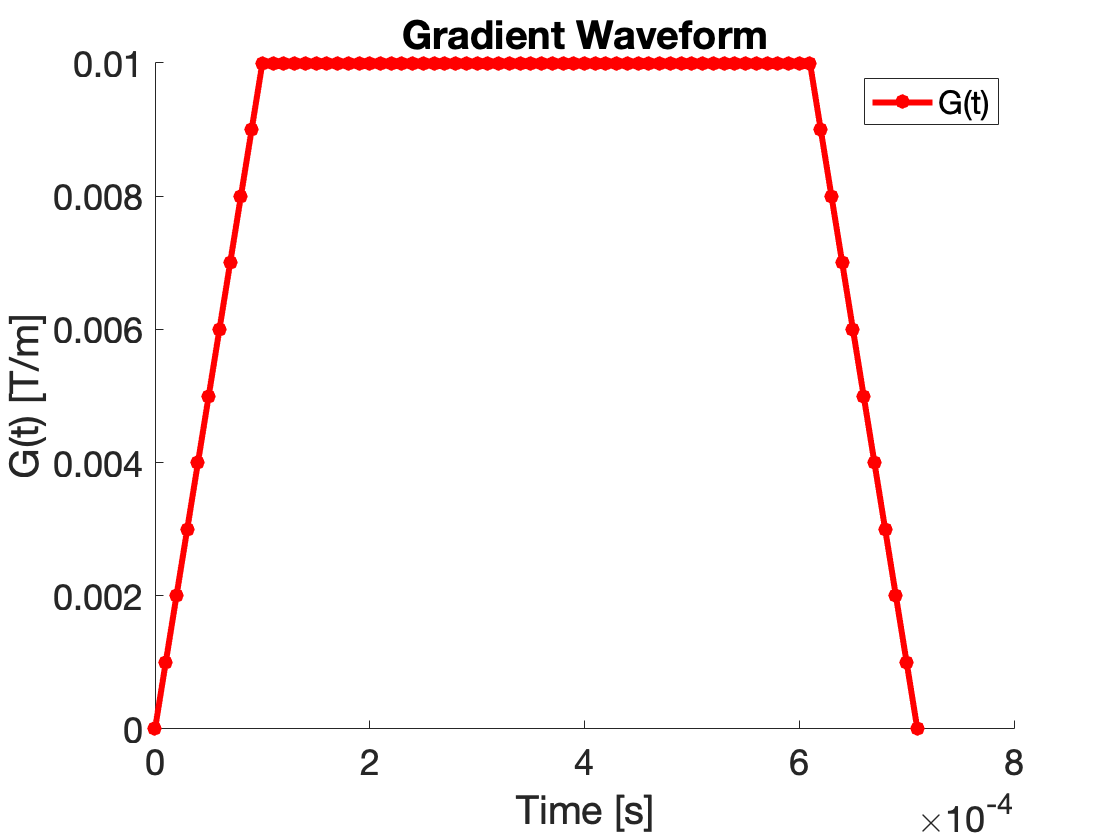

figure; hold on;
  title( 'Gradient Waveform' )  
  xlabel( 'Time [s]' ); ylabel( 'G(t) [T/m]' );
    plot( Gx.t , Gx.G , 'r.-' );  legend( 'G(t)' ); 

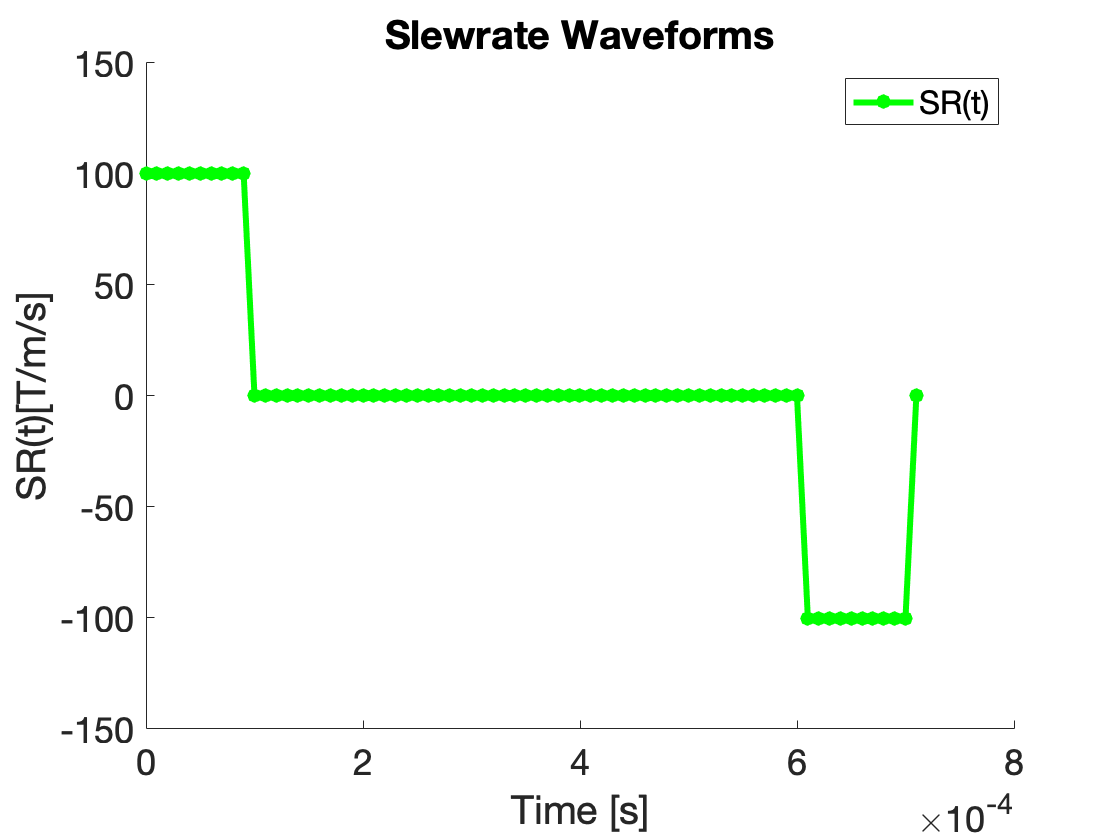


figure; hold on;
  title( 'Slewrate Waveforms' )  
  xlabel( 'Time [s]' ); ylabel( 'SR(t)[T/m/s]' );
    plot( Gx.t , Gx.SR , 'g.-' ); legend( 'SR(t)' ); 

## Define the eddy current response

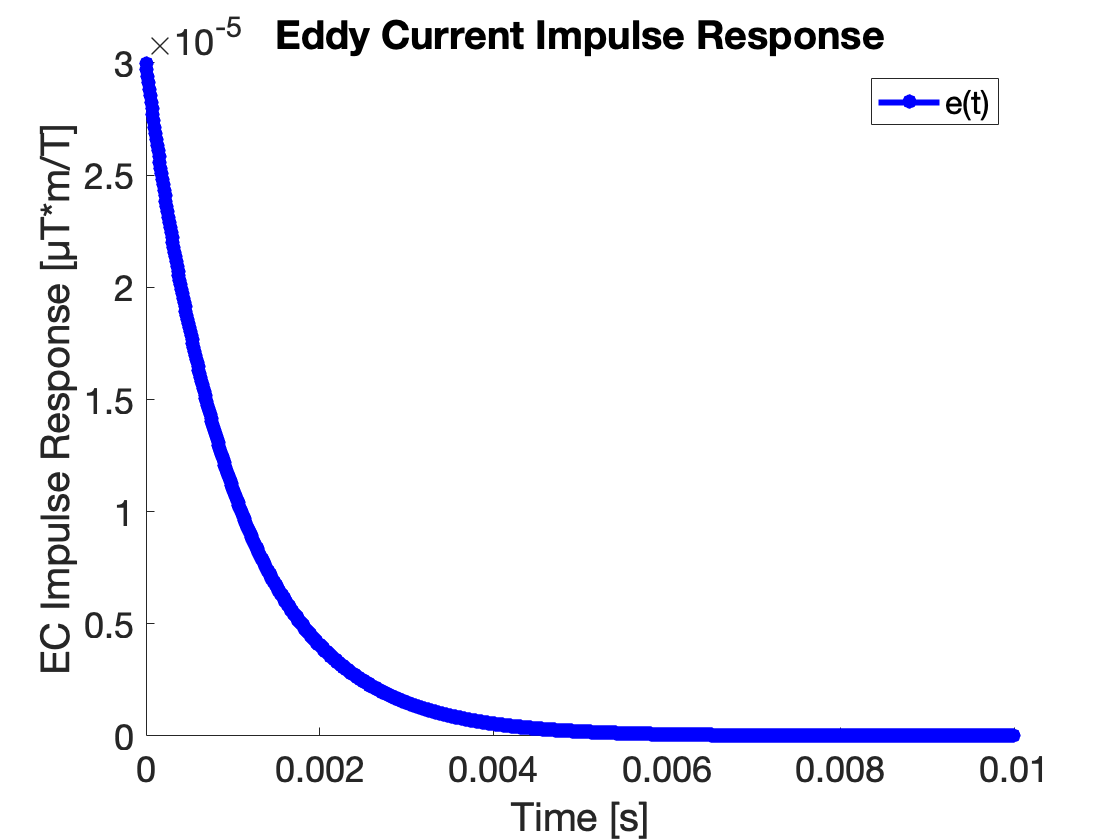

sys.tau(1) = 1.0e-3;                           % Eddy current time constant [s]
sys.alpha(1) = 30.0e-6;                        % Eddy current amplitude [µT*m/T]
t_eddy = 0 : sys.dt : 10 * ( max(sys.tau) );   % Time vector [ms]

% Add a second eddy current time constant
% sys.tau(2) = 5.0e-3;           % Eddy current time constant [s]
% sys.alpha(2) = 5.0e-6;         % Eddy current amplitude [µT*m/T]

e = zeros( 1 , length(t_eddy) );
for n = 1 : length(sys.tau)
  e = e + sys.alpha(n) * exp( -t_eddy / sys.tau(n) );
end

figure; hold on;
  title('Eddy Current Impulse Response')
  xlabel('Time [s]'); ylabel('EC Impulse Response [µT*m/T]');
  plot(t_eddy, e , 'b.-'); legend( 'e(t)' ); %xlim([0 max([max(t) max(t_eddy)])]);

## Define the resultant B0 eddy current field

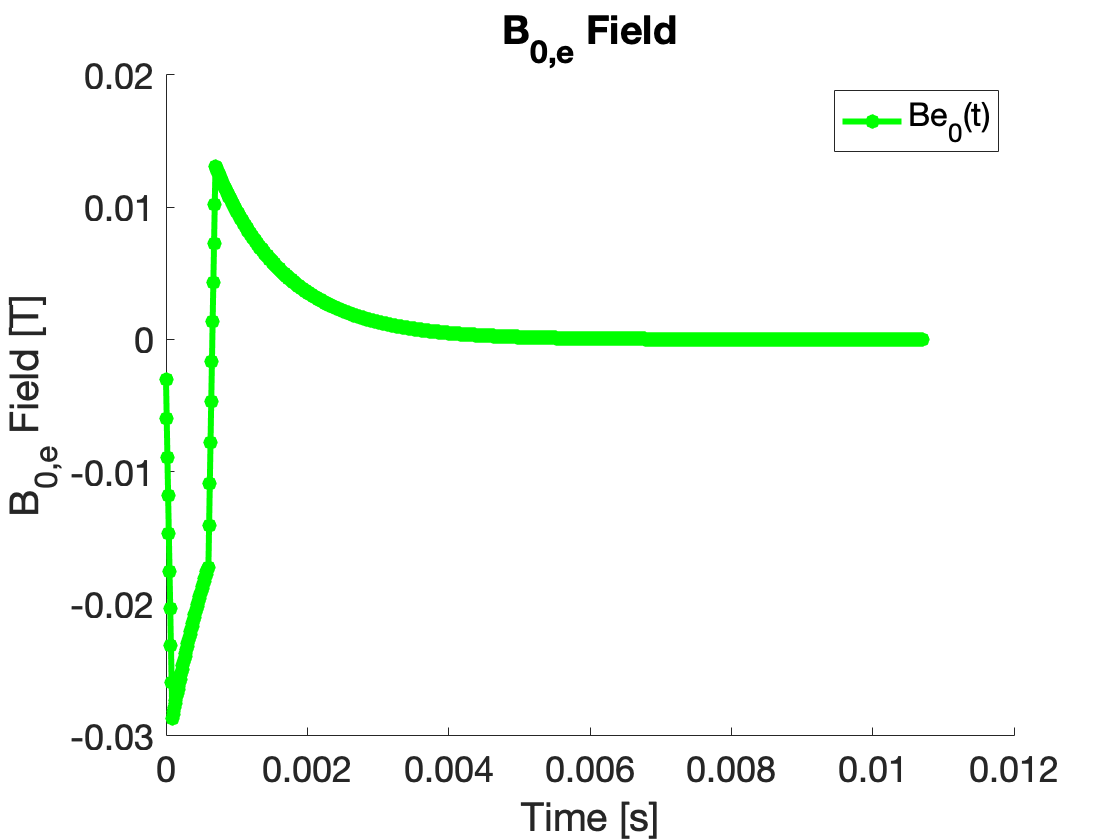

Be_0 = conv( -Gx.SR , e );  % Zeroth order eddy current [µT]
t_e = 0 : sys.dt : sys.dt * ( length(Be_0) - 1 );  % Time vector [s]

f=figure; hold on;
  title('B_{0,e} Field')  
  xlabel('Time [s]'); ylabel('B_{0,e} Field [T]');
  plot(t_e,Be_0,'g.-');
  legend('Be_0(t)'); 

  %xlim([0 max([max(t) max(t_eddy)])]);


## WRONG - Define the eddy current gradient vector [Be_0 + G]

G_e = Be_0 + [ Gx.G zeros( 1 , length(Be_0) - length(Gx.G) ) ];

## Define the effective B-field for several spatial positions

## Show the results

% set(groot,'defaultLineLineWidth',3,'defaultLineMarkerSize',25,'defaultAxesFontSize',15);
% f=figure; axis off; hold on;
% 
% ax1=axes('position',[0.15 0.625 0.80 0.30]); hold on;
%   title('Eddy Current Impulse Response')
%   xlabel('Time [s]'); ylabel('Imp. Response [???]');
%   plot(t_eddy,e,'b.-'); legend('e(t)'); xlim([0 max([max(t) max(t_eddy)])]);
%   
% ax1=axes('position',[0.15 0.125 0.80 0.30]); hold on;
%   title('Gradient and Slewrate Waveforms')  
%   xlabel('Time [s]'); ylabel('G(t) [T/m] or S(t)[T/m/s]');
%   plot(t,G,'r.-'); plot(t,S,'g.-'); legend('G(t)','S(t)'); xlim([0 max([max(t) max(t_eddy)])]);

f=figure; hold on;
  title('Target and Imperfect Gradient Waveforms')  
  xlabel('Time [s]'); ylabel('G(t) [T/m]');
  plot(t,G,'r.-'); plot(t_e,Be_0,'g.-'); plot(t_e,G_e,'b.-');
  legend('G(t)','Be_0(t)','G_e(t)'); xlim([0 max([max(t) max(t_eddy)])]);



## What if you use Be_0 to pre-emphasize the gradient waveform?

G_pre=-Be_0+[G zeros(1,length(Be_0)-length(G))];  % Add the *opposite* of Be_0
S_pre=[diff(G_pre) 0];                            % Slewrate calculation
B0_pre=conv(-S_pre,e);                            % Zeroth order eddy current
G_post=B0_pre+[G_pre zeros(1,length(B0_pre)-length(G_pre))];
t_post=0:sys.dt:sys.dt*(length(G_post)-1);  % Time vector [ms]

f=figure; hold on; %set(gca,'FontSize',18)

r1=plot(t_e,G_pre,'r.-');
r2=plot(t_e,S_pre,'g.-');
r3=plot(t_post,G_post,'b.-');
legend('G_{pre}(t)','Be_0(t)','G_{post}(t)');